Read the clip and play it

% [y,Fs] = audioread("singlenote2.mp3");
[y,Fs] = audioread("Anote.mp3");

y =          0         0
         0         0
         0         0
    0.0000    0.0000
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


Fs = 44100

yg = y(2000:end,2);
player = audioplayer(yg, Fs);
play(player);

Plot the signal `y`

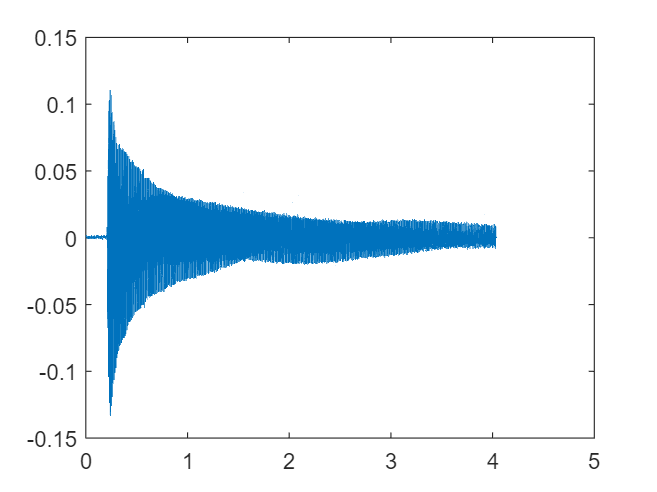

tg = 1/Fs*(0:(length(yg)-1))';
plot(tg,yg)

Compute the Fourier analysis

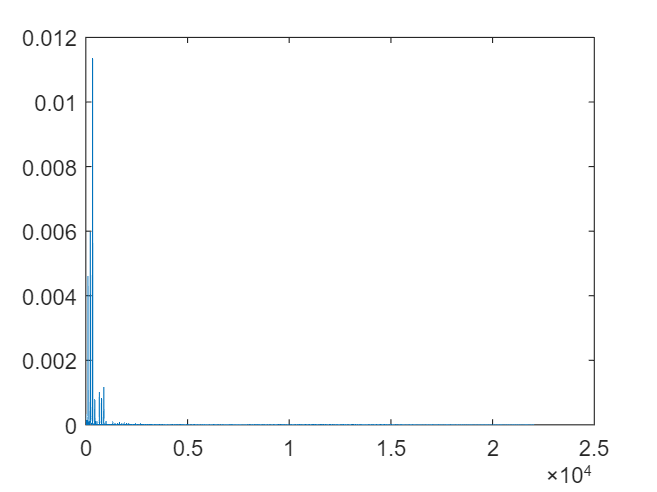

% FFT
N = numel(yg);
T = (tg(end)-tg(1))/length(tg);
Fs = 1/T;
F = fft(yg);
phase1 = angle(F/N);
phase2 = phase1(1:round(N/2+1));
P2 = (abs(F/N));
P1 = P2(1:round(N/2+1));
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(round(N/2)))/N;

plot(f,P1)

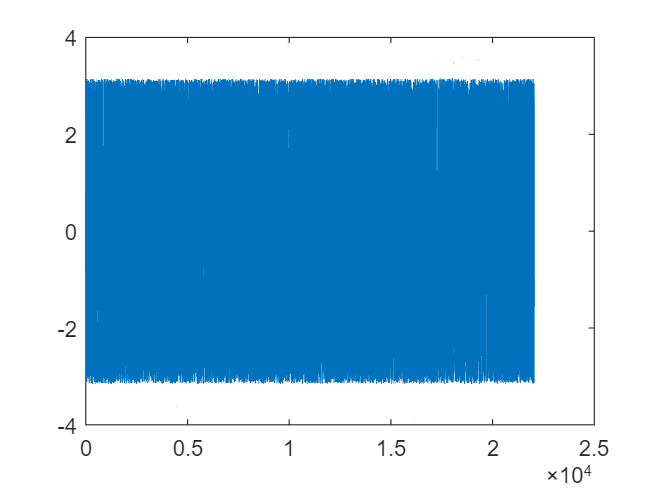

plot(f,phase2)

Identify the peak modes

minProm = 0.00005;
minDist = 400;
plot(f,P1)

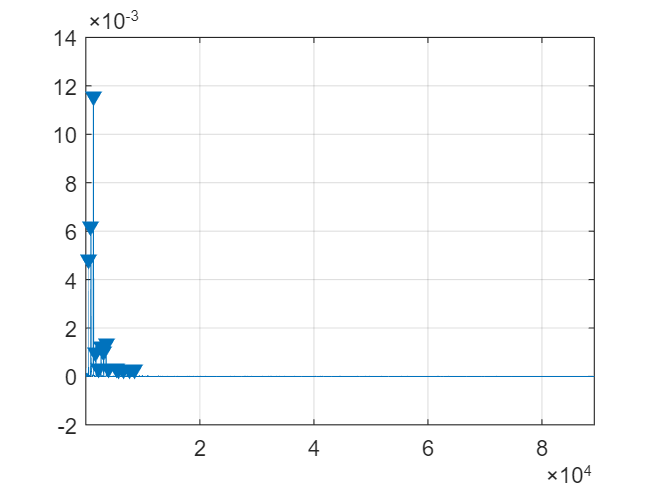

findpeaks(P1,"MinPeakProminence",minProm,"MinPeakDistance",minDist)

[value,idx] = findpeaks(P1,"MinPeakProminence",minProm,"MinPeakDistance",minDist);


Identify the peak magnitude by summing the peak and neighboring points

window = -2:1:2

window =     -2    -1     0     1     2


idxWindow = idx+window;
hMag = sum(P1(idxWindow),2)

hMag =     0.0137
    0.0207
    0.0263
    0.0027
    0.0003
    0.0030
    0.0025
    0.0038
    0.0005
    0.0004


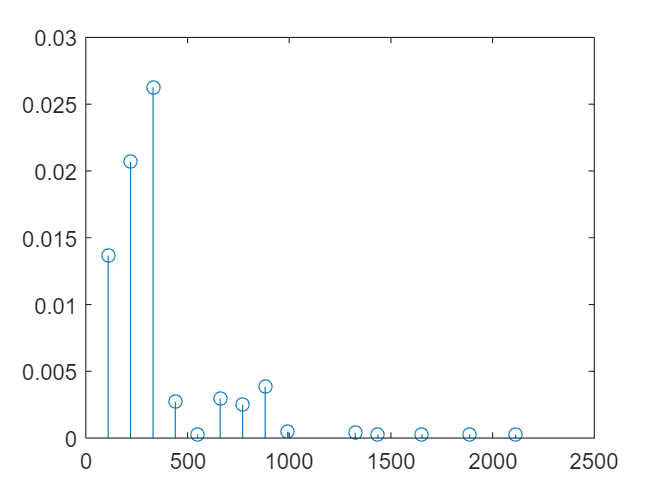

hFreq = f(idx);
stem(hFreq,hMag)

Plot the phases

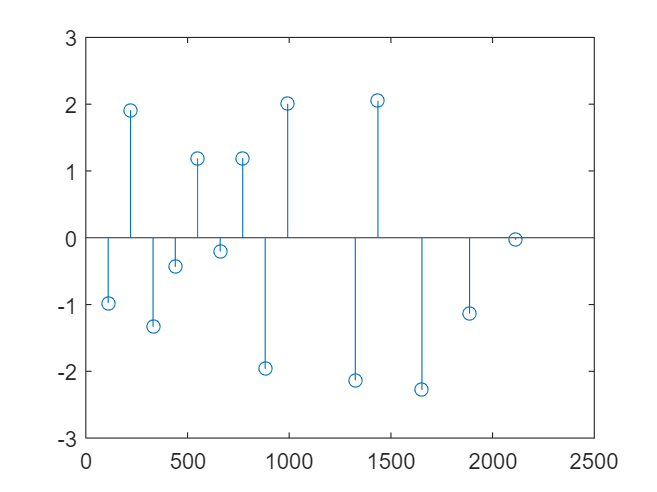

hPhase = phase2(idx);
stem(hFreq,hPhase)

Create a Fourier series using the magnitude and phase

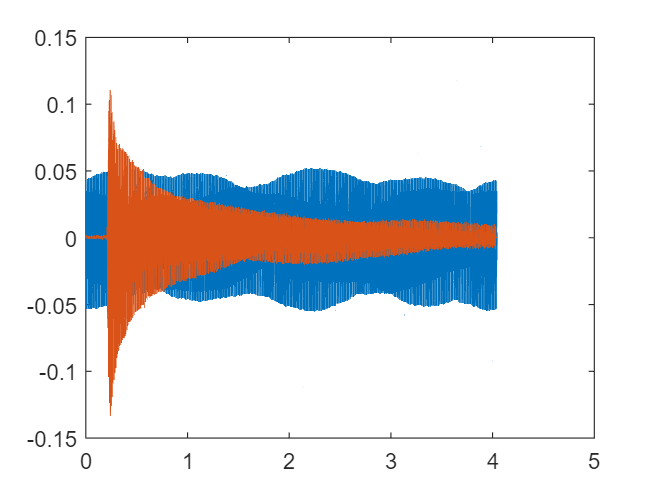

nFundamental = find(hFreq > 190,1);

yf = tg*0;
for k = nFundamental:numel(hMag)
    yf = yf + hMag(k)*cos(2*pi*hFreq(k)*tg + hPhase(k));
end    

plot(tg,yf,tg,yg)

player = audioplayer(yf, Fs);
play(player);

Now compute the short time fourier transform

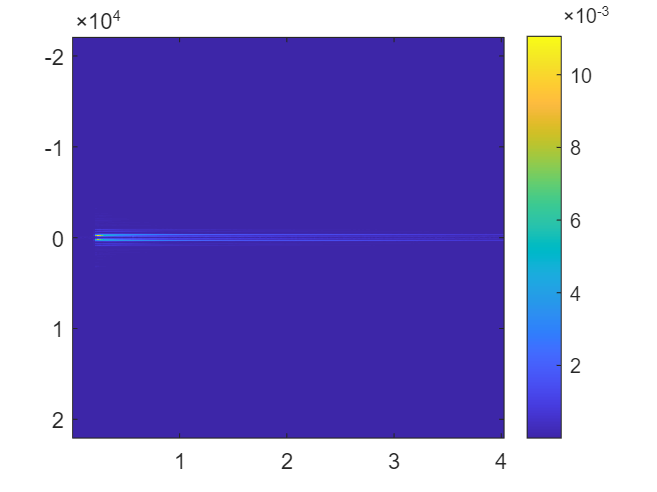

Ns = 512*4;
[s,f,t] = stft(yg,Fs,'Window',kaiser(Ns/2,5),'OverlapLength',256,'FFTLength',Ns);
p = abs(s/Ns);
% [p,f,t] = pspectrum(yg,Fs,'spectrogram',...
%         'FrequencyResolution',500,'OverlapPercent',99);

imagesc(t,f,p)
colorbar

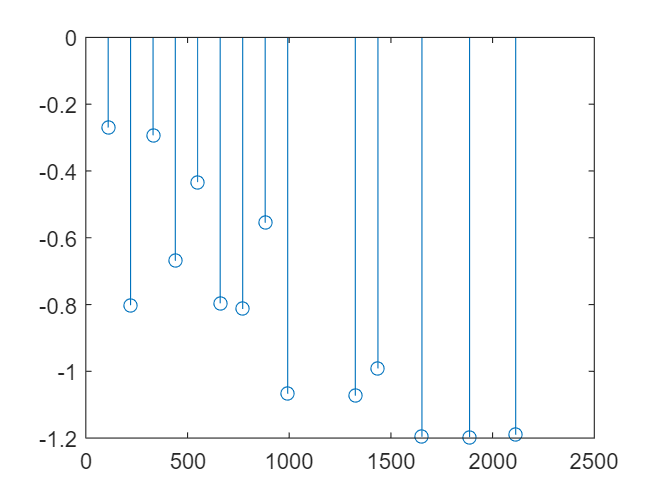


gamma = [];
h0 = [];
for k = 1:numel(hFreq)
    [value,idxp(k)] = min(abs(hFreq(k)-f));
    pk = p(idxp(k),:);
    expFit = fit(t,pk','exp1');
    h0(k) = expFit.a;
    gamma(k) = expFit.b;
end

stem(hFreq,gamma')

Create a Fourier series using the magnitude, phase, and decay

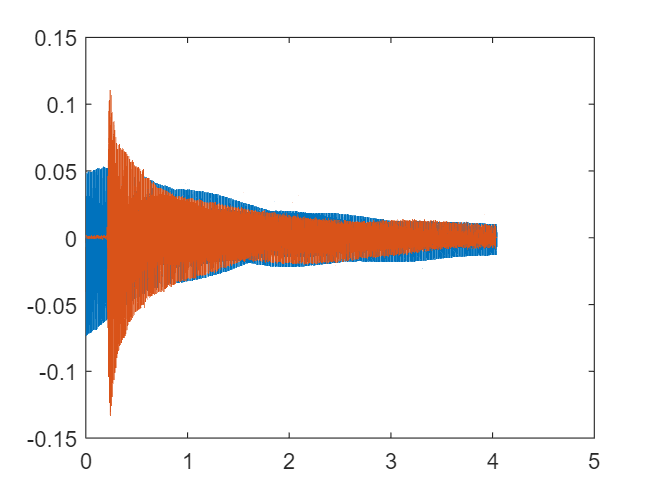

nFundamental = find(hFreq > 190,1);
nFundamental = 1;

yf2 = tg*0;
for k = nFundamental:numel(hMag)
    yf2 = yf2 + h0(k).*exp(gamma(k).*tg).*cos(2*pi*hFreq(k)*tg + hPhase(k));
end    

ratio = mean(abs(yg))./mean(abs(yf2));
h0 = h0*ratio;
for k = nFundamental:numel(hMag)
    yf2 = yf2 + h0(k).*exp(gamma(k).*tg).*cos(2*pi*hFreq(k)*tg + hPhase(k));
end    


plot(tg,yf2,tg,yg)
player = audioplayer(yf2, Fs);
play(player);
audiowrite("synthesized.wav",yf2,round(Fs))

pause(3)

player = audioplayer(yg, Fs);
play(player);
audiowrite("original.wav",yg,round(Fs))

Save the resulting frequencies, etc.

save fftSingleNoteAnalysis.mat h0 gamma tg yg hPhase hFreq Fs